# ASSIGNEMENT 1 -- AEROELASTICITY

clear; clc;

# Aeroelastic coefficients used for the subsequent calculations

This section introduces the main coefficients derived previously and required for the remainder of the aeroelastic analysis.  

The objective is not to repeat the full derivation, but rather to define, in a compact and reusable form, the intermediate quantities that will be used later for:

- the computation of the divergence dynamic pressure q_D

- the construction of the global aeroelastic matrix,

- and the evaluation of the control effectiveness E_C.

Whenever a coefficient is introduced numerically, its symbolic expression is also recalled for consistency with the analytical derivation.

### Numerical data

The following numerical values are taken from the statement:

EJ        = 1e7;      % [N.m^2]
GJ        = 1e6;      % [N.m^2]
EA        = 1e8;      % [N]
CL_alpha  = 2*pi;     % [-]
CMAC_beta = -0.1;     % [-]
b         = 14;       % [m]
c         = 1;        % [m]
e         = c/4 ;     % [m]
b_a       = 2.5;      % [m]
gamma_deg = 15;       % [deg]
CL_beta   = pi;       % [-]

Some additional geometric parameters are required by the model but are not given explicitly in the provided numerical table. They are therefore introduced separately and may be adjusted later depending on the selected configuration.

#### Additional geometric parameters

The reduced aeroelastic model also depends on the following geometric quantities:

- z_A : vertical distance entering the strut geometry,

- x_B : chordwise position of the strut attachment point. (This quantity will be a parameter later)

Since these quantities are not specified in the numerical table, they are defined here as explicit model parameters.

% Keep a value for z_A
z_A = 2.0;    % [m]

### Aerodynamic stiffness matrix

The aerodynamic stiffness matrix of the wing is written as

K_A1 = (c*b/4) * CL_alpha;
K_A2 = (e*c*b/3) * CL_alpha;

K_A = [0,   K_A1;
       0,   K_A2];

It is useful to isolate K_A1  and K_A2 explicitly, since both coefficients appear directly in the divergence condition.

### Aileron generalized load vector

The aileron contribution is introduced through the generalized aerodynamic load vector

F_a1 = (c/b) * CL_beta * (b^3 - (b-b_a)^3) / (3*b);
F_a2 = (c/b) * (e*CL_beta + c*CMAC_beta) * (b^2 - (b-b_a)^2) / 2;

F_a = [F_a1;
       F_a2];

These two terms will later be used in the expression of the generalized torsional displacement, and therefore in the control effectiveness formula.

### Structural stiffness matrix

The total structural stiffness matrix is written in the form

K_S11 = @(gamma, x_B) ...
    4*EJ/b^3 + EA*z_A^3/b^4 * (cos(gamma)^4 / sin(gamma));

K_S12 = @(gamma, x_B) ...
   -EA*z_A^2 * cos(gamma)^3 * x_B / b^3;

K_S22 = @(gamma, x_B) ...
    GJ/b + EA * sin(gamma) * cos(gamma)^2 * z_A * x_B^2 / b^2;

K_S = @(gamma, x_B) [ ...
    K_S11(gamma, x_B),   K_S12(gamma, x_B);
    K_S12(gamma, x_B),   K_S22(gamma, x_B) ...
];

The term K_S1 combines the wing bending stiffness and the strut-induced contribution. The coefficient K_S12 represents the bending–torsion coupling induced by the strut geometry. Finally, K_S2  gathers the torsional stiffness of the wing together with the additional contribution due to the strut.

## Divergence dynamic pressure

q_D = @(gamma, x_B) ...
    (K_S11(gamma, x_B) * K_S22(gamma, x_B) - K_S12(gamma, x_B)^2) ...
    / ...
    (K_S11(gamma, x_B) * K_A2 - K_S12(gamma, x_B) * K_A1);

#### Total aeroelastic matrix

For later use, the global reduced aeroelastic matrix is introduced as

% Total aeroelastic matrix
K_TOT = @(gamma, x_B, q) ...
    K_S(gamma, x_B) - q * K_A;

KT11 = @(gamma, x_B, q) K_S11(gamma, x_B);
KT12 = @(gamma, x_B, q) K_S12(gamma, x_B) - q * K_A1;
KT21 = @(gamma, x_B, q) K_S12(gamma, x_B);
KT22 = @(gamma, x_B, q) K_S22(gamma, x_B) - q * K_A2;

% Determinant of total aeroelastic matrix
det_KTOT = @(gamma, x_B, q) ...
    det(K_TOT(gamma, x_B, q));

## Control effectiveness

The control effectiveness is written as

E_C = @(gamma, x_B, q) ...
    1 ...
    + q * (b/b_a) * (CL_alpha/CL_beta) ...
    * (KT11(gamma, x_B, q) * F_a2 - KT21(gamma, x_B, q) * F_a1) ...
    / (2 * det_KTOT(gamma, x_B, q));

# Divergence dynamic pressure Vs x_B for different values of gamma

This code plots the divergence dynamic pressure qD as a function of the strut attachment position xB for a fixed angle γ=15°. The objective of the code is to identify how the structural location of the strut affects the onset of static aeroelastic divergence. It identifies the asymptotic position of the divergence, highlights the region where no finite divergence occurs, and marks the reference positions of the elastic axis and the aerodynamic center. The value qD(EA) is also displayed in order to compare the local divergence condition with the global trend of the curve. This representation makes it possible to interpret the sensitivity of divergence to the choice of xB and to visualize the geometrical configurations that are more critical from an aeroelastic stability point of view.

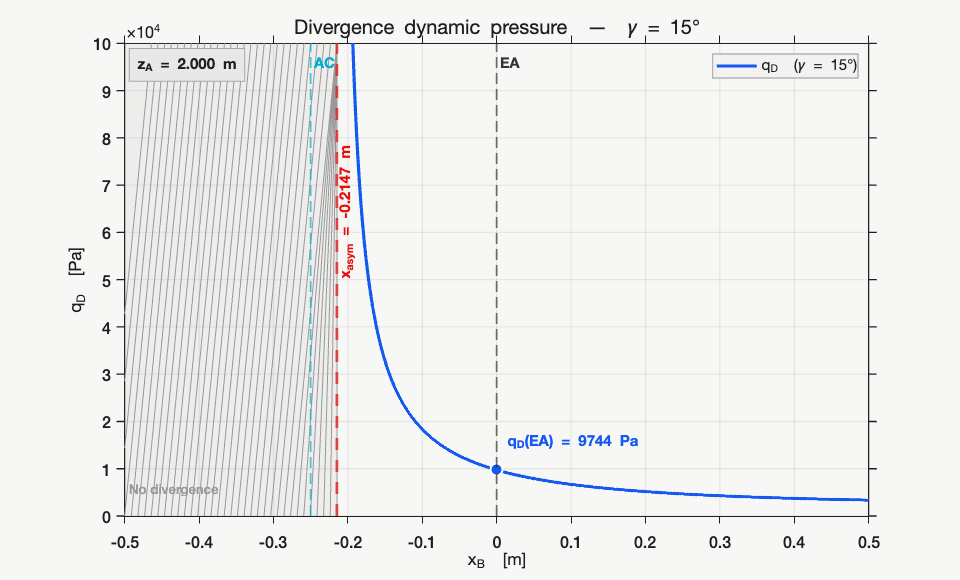

%% ── Divergence dynamic pressure vs x_B at γ = 15 deg ──────────────────
gamma     = deg2rad(gamma_deg);
x_B_vec   = linspace(-c/2, c/2, 4000);

%% Compute
qD_vec = arrayfun(@(xB) q_D(gamma, xB), x_B_vec);
qD_vec(~isfinite(qD_vec) | qD_vec <= 0) = NaN;

den_qD = @(xB) K_S11(gamma, xB)*K_A2 - K_S12(gamma, xB)*K_A1;
x_asym = -den_qD(0) / (den_qD(1) - den_qD(0));
qD_EA  = q_D(gamma, 0);

x_EA = 0;
x_AC = -c/4;

%% ── Palette ────────────────────────────────────────────────────────────
BG      = [0.97 0.97 0.96];
FG      = [0.12 0.12 0.12];
C_LEFT  = [0.08 0.35 0.95];  
C_ASYM  = [0.90 0.05 0.05];   
C_AC    = [0.00 0.68 0.82];  
C_EA    = [0.20 0.20 0.20];   
HATCH_C = [0.60 0.60 0.60];
Y_MAX   = 1e5;

%% ── Figure / axes ──────────────────────────────────────────────────────
fig = figure('Color', BG, 'Position', [100 80 960 580]);
ax  = axes('Parent', fig, ...
    'Color',     BG,      ...
    'XColor',    FG,      ...
    'YColor',    FG,      ...
    'GridColor', [0 0 0], ...
    'GridAlpha', 0.07,    ...
    'Box',       'on',    ...
    'LineWidth',  1.0,    ...
    'FontName',  'Helvetica Neue', ...
    'FontSize',   12,     ...
    'TickDir',   'out');
hold on; grid on;

xl = [min(x_B_vec), max(x_B_vec)];
yl = [0, Y_MAX];
xlim(xl); ylim(yl);

%% ── Hatch "no divergence" ───────────────────────────────────────────────
if x_asym > xl(1)
    x_L = xl(1);
    x_R = min(x_asym, xl(2));

    patch([x_L x_R x_R x_L], [yl(1) yl(1) yl(2) yl(2)], ...
          HATCH_C, 'FaceAlpha', 0.10, 'EdgeColor', 'none', ...
          'HandleVisibility', 'off');

    nH = 32;
    dx = (x_R - x_L) / nH;
    for k = -3:nH
        x0 = x_L + k*dx;
        x1 = min(x0 + 0.22*(x_R - x_L), x_R);
        line([x0 x1], [yl(1) yl(2)], ...
            'Color', [HATCH_C 0.40], 'LineWidth', 0.35, ...
            'Clipping', 'on', 'HandleVisibility', 'off');
    end

    text(x_L + 0.02*(x_R - x_L), yl(1) + 0.06*(yl(2)-yl(1)), ...
        'No divergence', ...
        'FontName','Helvetica Neue','FontSize',10, ...
        'Color', HATCH_C, 'HorizontalAlignment','left');
end

%% ── Plots ─────────────────────────────────────────────────────────────
eps_x = (xl(2)-xl(1)) * 2e-3;
idx_L = x_B_vec <  x_asym - eps_x;
idx_R = x_B_vec >  x_asym + eps_x;

plot(x_B_vec(idx_L), qD_vec(idx_L), ...
    'Color', C_LEFT, 'LineWidth', 2.4, ...
    'DisplayName', sprintf('q_D  (\\gamma = %.0f°)', gamma_deg));
plot(x_B_vec(idx_R), qD_vec(idx_R), ...
    'Color', C_LEFT, 'LineWidth', 2.4, ...
    'HandleVisibility', 'off');

%% ── References Verticals─────────────────────────────────────────────
xline(x_asym, 'Color', C_ASYM, 'LineStyle', '--', 'LineWidth', 2.0, ...
    'HandleVisibility', 'off');
xline(x_EA,   'Color', C_EA,   'LineStyle', '--', 'LineWidth', 1.2, ...
    'HandleVisibility', 'off');
xline(x_AC,   'Color', C_AC,   'LineStyle', '--', 'LineWidth', 1.2, ...
    'HandleVisibility', 'off');

%% ── Labels EA / AC ──────────────────────────────────────────────────────
text(x_EA + 0.005*(xl(2)-xl(1)), yl(2)*0.978, 'EA', ...
    'FontName','Helvetica Neue','FontSize',11,'FontWeight','bold', ...
    'Color', C_EA, 'HorizontalAlignment','left','VerticalAlignment','top');

text(x_AC + 0.005*(xl(2)-xl(1)), yl(2)*0.978, 'AC', ...
    'FontName','Helvetica Neue','FontSize',11,'FontWeight','bold', ...
    'Color', C_AC, 'HorizontalAlignment','left','VerticalAlignment','top');

%% ── Asymptote Label ───────────────────
text(x_asym + 0.025*(xl(2)-xl(1)), yl(1) + 0.5*(yl(2)-yl(1)), ...
    sprintf('x_{asym} = %.4f m', x_asym), ...
    'FontName','Helvetica Neue','FontSize',11,'FontWeight','bold', ...
    'Color', C_ASYM, ...
    'HorizontalAlignment','left','VerticalAlignment','bottom', ...
    'Rotation', 90);

%% ── q_D(EA) tag ──────────────────────────────────
if isfinite(qD_EA) && qD_EA > 0 && qD_EA <= Y_MAX
    plot(x_EA, qD_EA, 'o', ...
        'MarkerSize',  9, ...
        'MarkerFaceColor', C_LEFT, ...
        'MarkerEdgeColor', [1 1 1], ...
        'LineWidth',   1.5, ...
        'HandleVisibility', 'off');

    text(x_EA + 0.012*(xl(2)-xl(1)), qD_EA + 0.06*(yl(2)-yl(1)), ...
        sprintf('q_D(EA) = %.4g Pa', qD_EA), ...
        'FontName','Helvetica Neue','FontSize',11,'FontWeight','bold', ...
        'Color', C_LEFT, ...
        'HorizontalAlignment','left','VerticalAlignment','middle');
end

%% ── Boîte z_A Box ───────────────────────────────────────────────────────────
text(xl(1) + 0.015*(xl(2)-xl(1)), yl(2)*0.975, ...
    sprintf('z_A = %.3f m', z_A), ...
    'FontName','Helvetica Neue','FontSize',11,'FontWeight','bold', ...
    'Color', FG, 'HorizontalAlignment','left','VerticalAlignment','top', ...
    'BackgroundColor',[0.91 0.91 0.91],'EdgeColor',[0.65 0.65 0.65],'Margin',5);

%% ── Axes labels / titles / legend ──────────────────────────────────────
xlabel('x_B  [m]',  'Color',FG,'FontName','Helvetica Neue','FontSize',13);
ylabel('q_D  [Pa]', 'Color',FG,'FontName','Helvetica Neue','FontSize',13);
title(sprintf('Divergence dynamic pressure  —  \\gamma = %.0f°', gamma_deg), ...
    'Color',FG,'FontName','Helvetica Neue','FontSize',15,'FontWeight','normal');

lg = legend('Location','northeast','FontSize',11,'FontName','Helvetica Neue');
lg.TextColor = FG;
lg.EdgeColor = [0.70 0.70 0.70];
lg.Color     = [0.95 0.95 0.95];

# Control Effectiveness EC(q) and Identification of the Control Reversal Pressure qC

This section focuses exclusively on the variation of the control effectiveness EC with the dynamic pressure q, for several values of the strut angle γ, at a certain xB. The purpose of the code is to visualize how the aeroelastic response modifies the authority of the control surface as aerodynamic loading increases.

For each angle, the curve EC(q) is plotted over a truncated pressure range, and the region when EC<0  is highlighted.

The code also detects, for each configuration, the corresponding **pressure** qC, defined as the first value of dynamic pressure at which EC changes sign from positive to negative.

This plot therefore provides a direct comparison of the effect of γ on both the loss of control effectiveness and the onset of reversal.

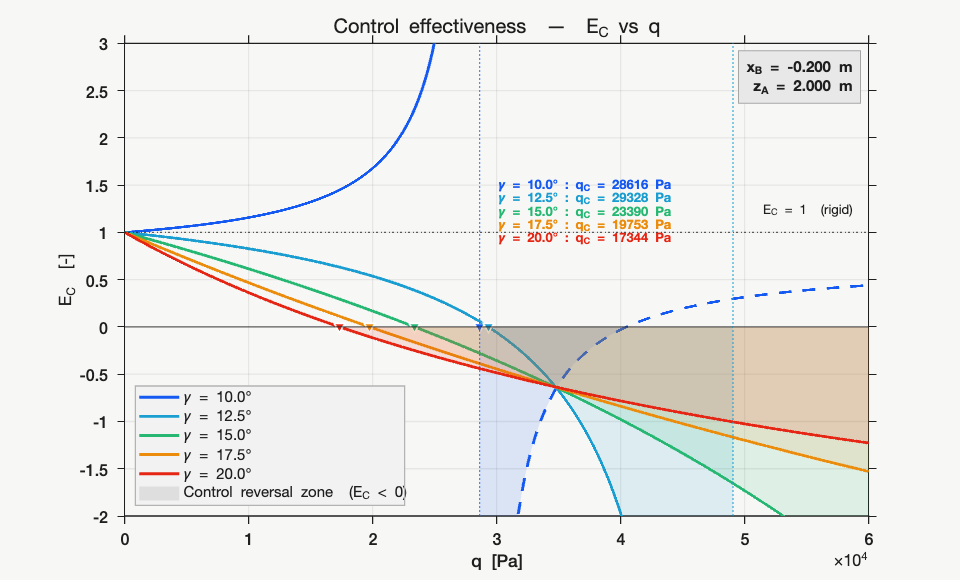

%% ── Control effectiveness E_C vs q for several γ values ────────────────

x_B_fixed  = -0.2;                        % [m]
q_max_plot = 6e4;                        % [Pa] 
q_vec      = linspace(0, q_max_plot, 5000);
gamma_degs = [10, 12.5, 15, 17.5, 20];   % [deg]

%% ── Palette ─────────────────────────────────────────────────────────────
CMAP = [ ...
    0.08  0.35  0.95;   % γ = 10°
    0.10  0.62  0.82;   % γ = 12.5°
    0.15  0.72  0.45;   % γ = 15°
    0.92  0.55  0.05;   % γ = 17.5°
    0.90  0.15  0.08;   % γ = 20°
];

Y_MIN = -2;
Y_MAX =  3;

%% ── Figure / axes ───────────────────────────────────────────────────────
fig = figure('Color', BG, 'Position', [100 80 960 580]);
ax  = axes('Parent', fig, ...
    'Color',     BG,      ...
    'XColor',    FG,      ...
    'YColor',    FG,      ...
    'GridColor', [0 0 0], ...
    'GridAlpha', 0.07,    ...
    'Box',       'on',    ...
    'LineWidth', 1.0,     ...
    'FontName',  'Helvetica Neue', ...
    'FontSize',  12,      ...
    'TickDir',   'out');
hold on; grid on;

xl = [0, q_max_plot];
yl = [Y_MIN, Y_MAX];
xlim(xl); ylim(yl);

%% ── Reference lines ────────────────────────────────────────────────
yline(0, 'Color', [FG 0.4], 'LineStyle', '-', 'LineWidth', 1, ...
    'HandleVisibility', 'off');

yline(1, 'Color', [FG 0.25], 'LineStyle', ':', 'LineWidth', 1, ...
    'HandleVisibility', 'off');

text(xl(2)*0.98, 1 + 0.03*(Y_MAX-Y_MIN), 'E_C = 1  (rigid)', ...
    'FontName','Helvetica Neue','FontSize',10,'Color',[FG 0.5], ...
    'HorizontalAlignment','right','VerticalAlignment','bottom');

%% ── Pre-allocation ──────────────────────────────────────────────────────
h = gobjects(numel(gamma_degs), 1);

%% ── Plot for each γ ─────────────────────────────────────────────────
for i = 1:numel(gamma_degs)
    gd  = gamma_degs(i);
    g   = deg2rad(gd);
    col = CMAP(i,:);

    % Compute E_C
    EC_vec = arrayfun(@(q) E_C(g, x_B_fixed, q), q_vec);
    EC_vec(~isfinite(EC_vec)) = NaN;

    % Compute q_D
    qD_i = q_D(g, x_B_fixed);

    % Mask
    valid_mask = isfinite(EC_vec);

    % -------- control reversal zone : E_C < 0 --------
    neg_mask = valid_mask & (EC_vec < 0);

    dmask   = diff([false, neg_mask, false]);
    i_start = find(dmask == 1);
    i_end   = find(dmask == -1) - 1;

    for k = 1:numel(i_start)
        idx = i_start(k):i_end(k);

        x_patch = [q_vec(idx), fliplr(q_vec(idx))];
        y_patch = [EC_vec(idx), zeros(size(idx))];

        patch('XData', x_patch, 'YData', y_patch, ...
              'FaceColor', col, ...
              'FaceAlpha', 0.12, ...
              'EdgeColor', 'none', ...
              'HandleVisibility', 'off');
    end

    % -------- Plot --------
    if isfinite(qD_i) && qD_i > 0 && qD_i <= xl(2)
        eps_q = (xl(2)-xl(1)) * 2e-3;
        idx_L = q_vec <  qD_i - eps_q;
        idx_R = q_vec >  qD_i + eps_q;

        h(i) = plot(q_vec(idx_L), EC_vec(idx_L), ...
            'Color', col, 'LineWidth', 2.2, ...
            'DisplayName', sprintf('\\gamma = %.1f°', gd));

        plot(q_vec(idx_R), EC_vec(idx_R), ...
            'Color', col, 'LineWidth', 2.2, 'LineStyle', '--', ...
            'HandleVisibility', 'off');

        xline(qD_i, 'Color', [col 0.35], 'LineStyle', ':', ...
            'LineWidth', 1.0, 'HandleVisibility', 'off');
    else
        h(i) = plot(q_vec, EC_vec, ...
            'Color', col, 'LineWidth', 2.2, ...
            'DisplayName', sprintf('\\gamma = %.1f°', gd));
    end

    % -------- q_C : from E_C > 0 to E_C < 0 --------
    sign_change = find( ...
        valid_mask(1:end-1) & valid_mask(2:end) & ...
        (EC_vec(1:end-1) > 0) & (EC_vec(2:end) < 0), ...
        1, 'first');

    if ~isempty(sign_change)
        q1 = q_vec(sign_change);
        q2 = q_vec(sign_change + 1);
        E1 = EC_vec(sign_change);
        E2 = EC_vec(sign_change + 1);

        % linear interpolation to get the pressure of sign change of EC
        q_rev = q1 - E1 * (q2 - q1) / (E2 - E1);

        % tag on E_C = 0
        plot(q_rev, 0, 'v', ...
            'MarkerSize', 7, ...
            'MarkerFaceColor', col, ...
            'MarkerEdgeColor', [1 1 1], ...
            'LineWidth', 1.2, ...
            'HandleVisibility', 'off');

        % tags for the control reversal pressures plotted
        x_txt = 3e4;
        y_txt = 1.5 - (i-1)*0.14;

        text(x_txt, y_txt, ...
            sprintf('\\gamma = %.1f° : q_C = %.0f Pa', gd, q_rev), ...
            'Color', col, ...
            'FontSize', 9.5, ...
            'FontName', 'Helvetica Neue', ...
            'HorizontalAlignment', 'left', ...
            'VerticalAlignment', 'middle', ...
            'FontWeight', 'bold');
    end
end

%% ── box for (x_B and z_A) ──────────────────────────────────────
text(xl(2) - 0.02*(xl(2)-xl(1)), yl(2) - 0.03*(yl(2)-yl(1)), ...
    sprintf('x_B = %.3f m\nz_A = %.3f m', x_B_fixed, z_A), ...
    'FontName','Helvetica Neue','FontSize',11,'FontWeight','bold', ...
    'Color', FG, ...
    'HorizontalAlignment','right','VerticalAlignment','top', ...
    'BackgroundColor',[0.91 0.91 0.91], ...
    'EdgeColor',     [0.65 0.65 0.65], ...
    'Margin', 5);

%% ── Legend reversal zone  ──────────────────────────────────────────────
patch([NaN NaN NaN NaN], [NaN NaN NaN NaN], [0.3 0.3 0.3], ...
      'FaceAlpha', 0.12, 'EdgeColor', 'none', ...
      'DisplayName', 'Control reversal zone  (E_C < 0)');

%% ── Axes /titles/legend ──────────────────────────────────────
xlabel('q  [Pa]',  'Color',FG,'FontName','Helvetica Neue','FontSize',13);
ylabel('E_C  [-]', 'Color',FG,'FontName','Helvetica Neue','FontSize',13);
title('Control effectiveness  —  E_C vs q', ...
    'Color',FG,'FontName','Helvetica Neue','FontSize',15,'FontWeight','normal');

lg = legend('Location','southwest','FontSize',11,'FontName','Helvetica Neue');
lg.TextColor = FG;
lg.EdgeColor = [0.70 0.70 0.70];
lg.Color     = [0.95 0.95 0.95];

# Wing deformed shape - Strut effect

This section compares the wing deformed shape with and without the strut for the selected configuration. The objective is to quantify how the strut modifies the bending–torsion response and to visualize the corresponding deformation.

The relative deviation is evaluated from $\delta_z(\%) = 100\,\frac{|z_{\mathrm{strut}}-z_{\mathrm{ns}}|}{|z_{\mathrm{ns}}|}$

The relative deviation is physically meaningful only where the reference deformation z_ns is itself non-negligible. Near the root (y -> 0), both z_ns and (z_strut - z_ns) vanish, but their ratio diverges due to the quadratic scaling Z ~ (y/b)^2. In this region, the absolute gap between the two configurations is a small fraction of the tip deflection — rendering the relative metric numerically degenerate and physically irrelevant.

A masking threshold is therefore introduced: y_min is defined as the first spanwise station where the absolute gap |z_strut - z_ns|, evaluated at x = c/4 (where torsion-induced differences are maximum), reaches 10% of its tip value. Below y_min, all relative-deviation plots are suppressed.

The 3D overlay is displayed twice:

- Full span : for physical context and deformation shape assessment

- From y_min : for meaningful relative comparison between configurations

The first spanwise cut in Figures 3 and 4 is set to y_min.

%% DATA
beta0_deg      = 10;
beta0          = deg2rad(beta0_deg);
x_B_fixed  = 0.1; 

%% q_D no strut (ns)
K_S11_ns = @(g, xB) 4*EJ/b^3;
K_S12_ns = @(g, xB) 0;
K_S22_ns = @(g, xB) GJ/b;

q_D_ns = (K_S11_ns(gamma, x_B_fixed) * K_S22_ns(gamma, x_B_fixed) ...
         - K_S12_ns(gamma, x_B_fixed)^2) ...
         / (K_S11_ns(gamma, x_B_fixed) * K_A2 ...
         - K_S12_ns(gamma, x_B_fixed) * K_A1);

%% Pressure of computation
q_eval = 0.4 * q_D_ns;

%% Grid (x, y) — starts just above root to avoid z_ns = 0
Nx    = 60;
Ny    = 800;
x_vec = linspace(-c/2, c/2, Nx);
y_vec = linspace(1e-4, b, Ny);
[XX, YY] = meshgrid(x_vec, y_vec);

%% Deformed shapes
z_strut = compute_z( ...
    K_S11(gamma, x_B_fixed), ...
    K_S12(gamma, x_B_fixed), ...
    K_S22(gamma, x_B_fixed), ...
    q_eval, K_A, F_a, beta0, XX, YY, b);

z_ns = compute_z( ...
    K_S11_ns(gamma, x_B_fixed), ...
    K_S12_ns(gamma, x_B_fixed), ...
    K_S22_ns(gamma, x_B_fixed), ...
    q_eval, K_A, F_a, beta0, XX, YY, b);

%% ── Find y_min : first y where |dz| >= 10% of tip value at x = c/4 ────
[~, ix_ref] = min(abs(x_vec - c/4));
dz_ref      = abs(z_strut(:, ix_ref) - z_ns(:, ix_ref));
tip_val     = dz_ref(end);
threshold   = 0.1 * tip_val;

idx_ymin = find(dz_ref >= threshold, 1, 'first');
if isempty(idx_ymin)
    idx_ymin = 1;
end
y_min = y_vec(idx_ymin);

fprintf('y_min (10%% tip gap threshold at x = c/4) = %.3f m  (%.1f%% span)\n', ...
    y_min, 100*y_min/b);

y_min (10% tip gap threshold at x = c/4) = 4.310 m  (30.8% span)


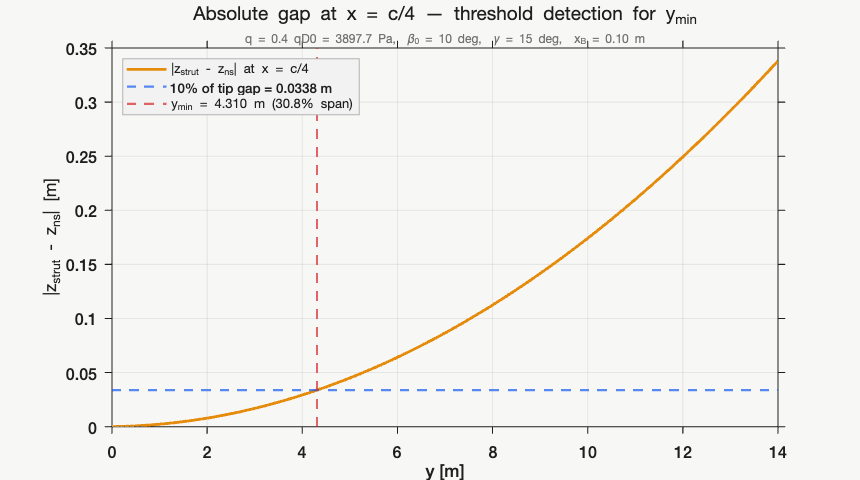


%% ── Relative deviation in percent ──────────────────────────────────────
DeltaZ_full_pct = 100 * abs(z_strut - z_ns) ./ abs(z_ns);
DeltaZ_full_pct(~isfinite(DeltaZ_full_pct)) = NaN;

%% Restricted grids
mask_y        = y_vec >= y_min;
y_vec_r       = y_vec(mask_y);
XX_r          = XX(mask_y, :);
YY_r          = YY(mask_y, :);
z_strut_r     = z_strut(mask_y, :);
z_ns_r        = z_ns(mask_y, :);
DeltaZ_r_pct  = DeltaZ_full_pct(mask_y, :);

%% Palette
BG   = [0.97 0.97 0.96];
FG   = [0.12 0.12 0.12];
FNT  = 'Helvetica Neue';
C_ST = [0.90 0.55 0.05];
C_NS = [0.08 0.35 0.95];

param_str = sprintf( ...
    'q = 0.4 qD0 = %.1f Pa,  \\beta_0 = %.0f deg,  \\gamma = %.0f deg,  x_B = %.2f m', ...
    q_eval, beta0_deg, gamma_deg, x_B_fixed);

%% Cuts 
y_cuts = [b/4, b/2, 3*b/4, b];
x_cuts = [-c/4, 0, c/4];

CMAP_y = [0.08 0.35 0.95;
          0.10 0.70 0.30;
          0.90 0.55 0.05;
          0.90 0.15 0.08];

CMAP_x = [0.08 0.35 0.95;
          0.90 0.15 0.08;
          0.15 0.72 0.35];

%% ── MANUAL LIMITS PER FIGURE ───────────────────────────────────────────
% Leave [] for automatic scaling.

% Fig 0
XLIM_FIG0 = [];
YLIM_FIG0 = [];

% Fig 1a
XLIM_FIG1A = [];
YLIM_FIG1A = [];
ZLIM_FIG1A = [];
CLIM_FIG1A = [];

% Fig 1b
XLIM_FIG1B = [];
YLIM_FIG1B = [];
ZLIM_FIG1B = [];
CLIM_FIG1B = [];

% Fig 2
XLIM_FIG2 = [];
YLIM_FIG2 = [];
ZLIM_FIG2 = [];
CLIM_FIG2 = [];

% Fig 3
XLIM_FIG3 = [];
YLIM_FIG3 = [60 100];

% Fig 4
XLIM_FIG4 = [];
YLIM_FIG4 = [50 100];

%% ════════════════════════════════════════════════════════════════════════
%  FIG 0 — 2D cut (y,z) at x = c/4 : absolute gap, full span, threshold
%% ════════════════════════════════════════════════════════════════════════
fig0 = figure('Color', BG, 'Position', [40 60 860 480]);
ax0  = setup_ax2d(fig0, FNT, FG, BG);

plot(ax0, y_vec, dz_ref, 'Color', C_ST, 'LineWidth', 2.2, ...
    'DisplayName', '|z_{strut} - z_{ns}| at x = c/4');

yline(ax0, threshold, '--', 'Color', C_NS, 'LineWidth', 1.6, ...
    'DisplayName', sprintf('10%% of tip gap = %.4f m', threshold));

xline(ax0, y_min, '--', 'Color', [0.85 0.15 0.15], 'LineWidth', 1.6, ...
    'DisplayName', sprintf('y_{min} = %.3f m (%.1f%% span)', y_min, 100*y_min/b));

xlabel(ax0, 'y [m]', 'Color', FG, 'FontName', FNT, 'FontSize', 13);
ylabel(ax0, '|z_{strut} - z_{ns}| [m]', 'Color', FG, 'FontName', FNT, 'FontSize', 13);
title(ax0, 'Absolute gap at x = c/4 — threshold detection for y_{min}', ...
    'Color', FG, 'FontName', FNT, 'FontSize', 14, 'FontWeight', 'normal');
subtitle(ax0, param_str, 'Color', [0.45 0.45 0.45], 'FontName', FNT, 'FontSize', 9);
add_legend(ax0, FNT, FG);

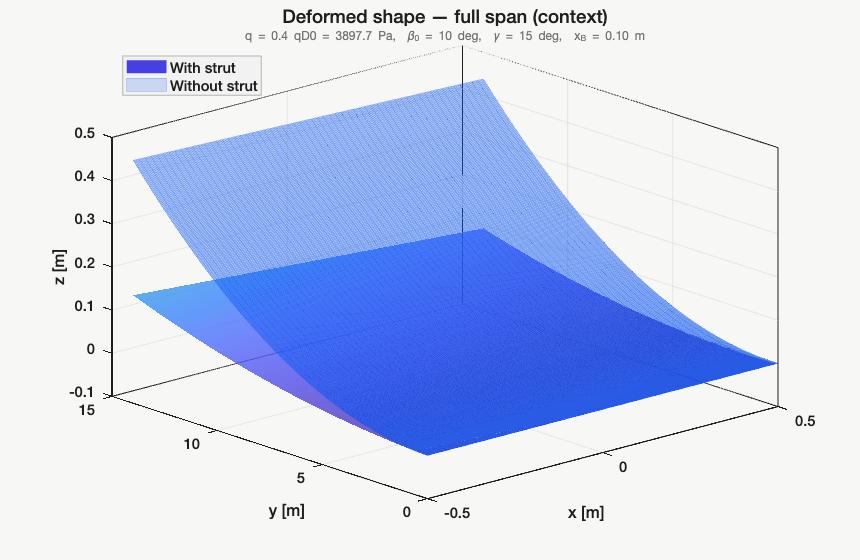

apply_limits(ax0, XLIM_FIG0, YLIM_FIG0, [], []);

%% ════════════════════════════════════════════════════════════════════════
%  FIG 1a — 3D overlay, full span
%% ════════════════════════════════════════════════════════════════════════
fig1a = figure('Color', BG, 'Position', [60 60 860 560]);
ax1a  = setup_ax3d(fig1a, FNT, FG, BG);

s1a = surf(ax1a, XX, YY, z_strut, 'EdgeColor', 'none', 'FaceAlpha', 0.75);
colormap(ax1a, parula);
s2a = surf(ax1a, XX, YY, z_ns, ...
    'EdgeColor', C_NS, 'EdgeAlpha', 0.22, ...
    'FaceColor', C_NS, 'FaceAlpha', 0.18);

legend(ax1a, [s1a, s2a], {'With strut', 'Without strut'}, ...
    'Location', 'northwest', 'FontSize', 11, 'FontName', FNT, ...
    'TextColor', FG, 'EdgeColor', [0.70 0.70 0.70], 'Color', [0.95 0.95 0.95]);

title(ax1a, 'Deformed shape — full span (context)', ...
    'Color', FG, 'FontName', FNT, 'FontSize', 14, 'FontWeight', 'normal');
subtitle(ax1a, param_str, 'Color', [0.45 0.45 0.45], 'FontName', FNT, 'FontSize', 9);

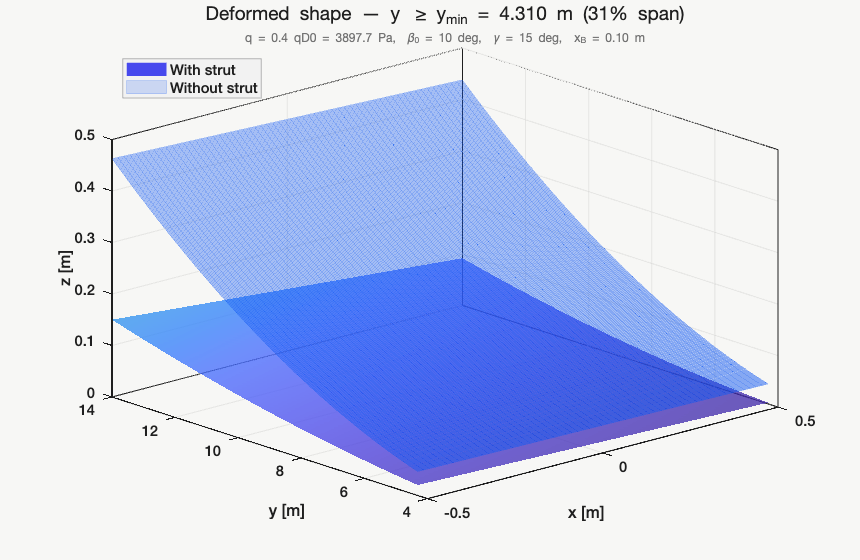

apply_limits(ax1a, XLIM_FIG1A, YLIM_FIG1A, ZLIM_FIG1A, CLIM_FIG1A);

%% ════════════════════════════════════════════════════════════════════════
%  FIG 1b — 3D overlay from y_min
%% ════════════════════════════════════════════════════════════════════════
fig1b = figure('Color', BG, 'Position', [80 60 860 560]);
ax1b  = setup_ax3d(fig1b, FNT, FG, BG);

s1b = surf(ax1b, XX_r, YY_r, z_strut_r, 'EdgeColor', 'none', 'FaceAlpha', 0.75);
colormap(ax1b, parula);
s2b = surf(ax1b, XX_r, YY_r, z_ns_r, ...
    'EdgeColor', C_NS, 'EdgeAlpha', 0.22, ...
    'FaceColor', C_NS, 'FaceAlpha', 0.18);

legend(ax1b, [s1b, s2b], {'With strut', 'Without strut'}, ...
    'Location', 'northwest', 'FontSize', 11, 'FontName', FNT, ...
    'TextColor', FG, 'EdgeColor', [0.70 0.70 0.70], 'Color', [0.95 0.95 0.95]);

title(ax1b, sprintf('Deformed shape — y \\geq y_{min} = %.3f m (%.0f%% span)', ...
    y_min, 100*y_min/b), ...
    'Color', FG, 'FontName', FNT, 'FontSize', 14, 'FontWeight', 'normal');
subtitle(ax1b, param_str, 'Color', [0.45 0.45 0.45], 'FontName', FNT, 'FontSize', 9);

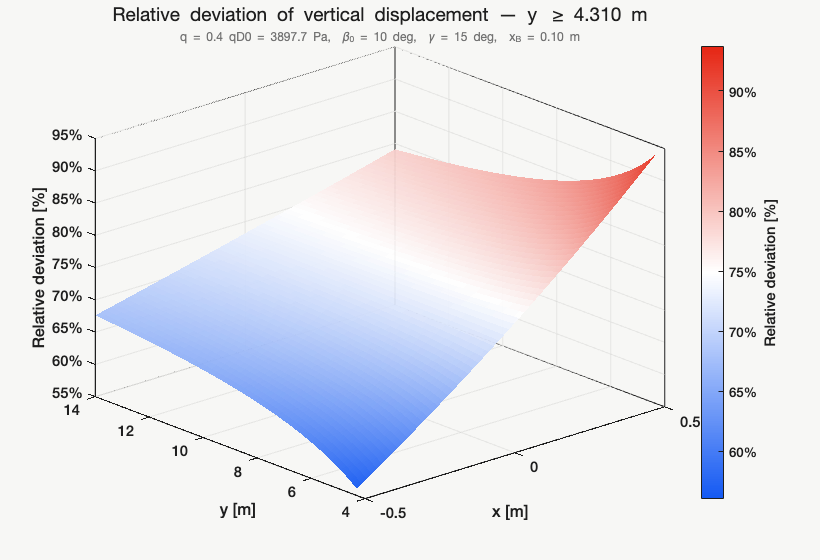

apply_limits(ax1b, XLIM_FIG1B, YLIM_FIG1B, ZLIM_FIG1B, CLIM_FIG1B);

%% ════════════════════════════════════════════════════════════════════════
%  FIG 2 — 3D relative deviation from y_min
%% ════════════════════════════════════════════════════════════════════════
fig2 = figure('Color', BG, 'Position', [100 60 820 560]);
ax2  = setup_ax3d(fig2, FNT, FG, BG);

surf(ax2, XX_r, YY_r, DeltaZ_r_pct, 'EdgeColor', 'none', 'FaceAlpha', 0.93);
colormap(ax2, bluewhitered(256));

zlabel(ax2, 'Relative deviation [%]', 'Color', FG, 'FontName', FNT, 'FontSize', 12);

cb2 = colorbar(ax2);
style_cb(cb2, 'Relative deviation [%]', FNT, FG);

title(ax2, sprintf('Relative deviation of vertical displacement — y \\geq %.3f m', y_min), ...
    'Color', FG, 'FontName', FNT, 'FontSize', 14, 'FontWeight', 'normal');
subtitle(ax2, param_str, 'Color', [0.45 0.45 0.45], 'FontName', FNT, 'FontSize', 9);

apply_limits(ax2, XLIM_FIG2, YLIM_FIG2, ZLIM_FIG2, CLIM_FIG2);
refresh_percent_format(ax2, 'z');
refresh_percent_colorbar(cb2);

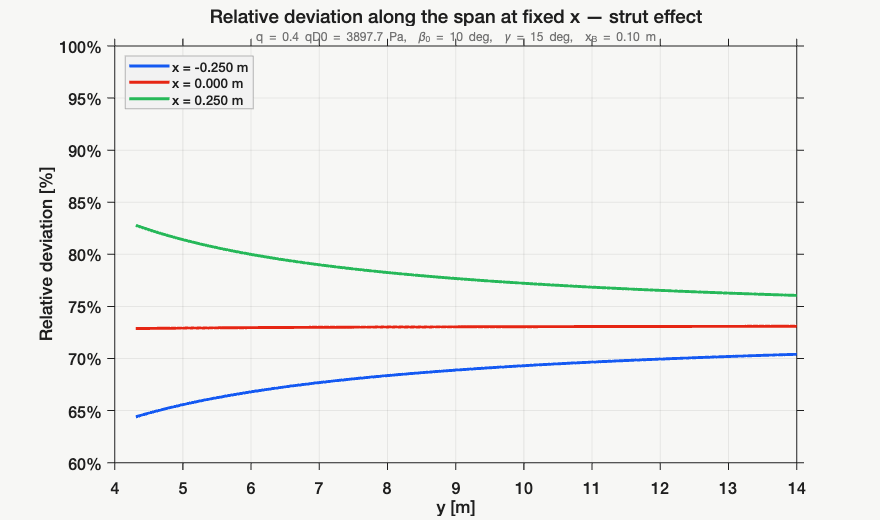


%% ════════════════════════════════════════════════════════════════════════
%  FIG 3 — 2D cuts along span at fixed x, from y_min
%% ════════════════════════════════════════════════════════════════════════
fig3 = figure('Color', BG, 'Position', [120 60 880 520]);
ax3  = setup_ax2d(fig3, FNT, FG, BG);
yline(ax3, 0, 'Color', [FG 0.35], 'LineWidth', 1.0, 'HandleVisibility', 'off');

for k = 1:numel(x_cuts)
    [~, ix] = min(abs(x_vec - x_cuts(k)));
    plot(ax3, y_vec_r, DeltaZ_r_pct(:, ix), '-', ...
        'Color', CMAP_x(k,:), 'LineWidth', 2.2, ...
        'DisplayName', sprintf('x = %.3f m', x_cuts(k)));
end

xlabel(ax3, 'y [m]', 'Color', FG, 'FontName', FNT, 'FontSize', 13);
ylabel(ax3, 'Relative deviation [%]', 'Color', FG, 'FontName', FNT, 'FontSize', 13);

title(ax3, 'Relative deviation along the span at fixed x — strut effect', ...
    'Color', FG, 'FontName', FNT, 'FontSize', 14, 'FontWeight', 'normal');
add_legend(ax3, FNT, FG);
subtitle(ax3, param_str, 'Color', [0.45 0.45 0.45], 'FontName', FNT, 'FontSize', 9);

apply_limits(ax3, XLIM_FIG3, YLIM_FIG3, [], []);
refresh_percent_format(ax3, 'y');

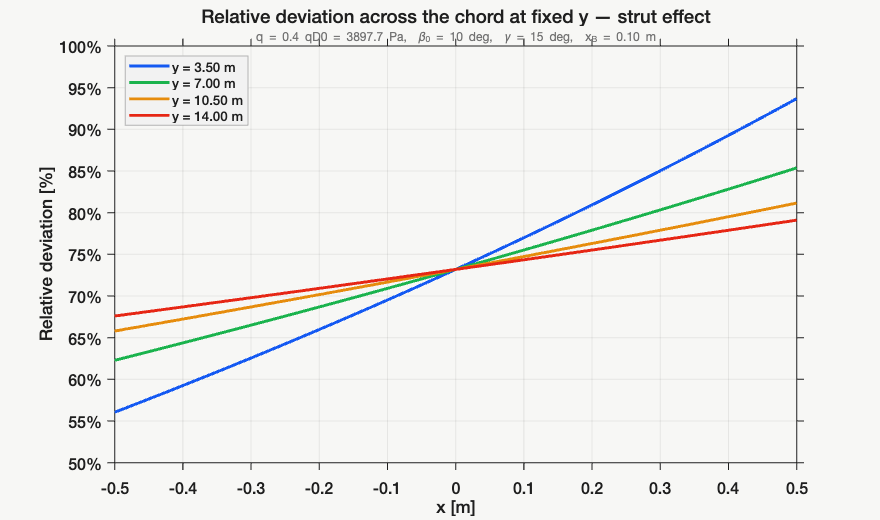


%% ════════════════════════════════════════════════════════════════════════
%  FIG 4 — 2D cuts across chord at fixed y >= y_min
%% ════════════════════════════════════════════════════════════════════════
fig4 = figure('Color', BG, 'Position', [140 60 880 520]);
ax4  = setup_ax2d(fig4, FNT, FG, BG);
yline(ax4, 0, 'Color', [FG 0.35], 'LineWidth', 1.0, 'HandleVisibility', 'off');

for k = 1:numel(y_cuts)
    [~, iy] = min(abs(y_vec_r - y_cuts(k)));
    plot(ax4, x_vec, DeltaZ_r_pct(iy, :), '-', ...
        'Color', CMAP_y(k,:), 'LineWidth', 2.2, ...
        'DisplayName', sprintf('y = %.2f m', y_cuts(k)));
end

xlabel(ax4, 'x [m]', 'Color', FG, 'FontName', FNT, 'FontSize', 13);
ylabel(ax4, 'Relative deviation [%]', 'Color', FG, 'FontName', FNT, 'FontSize', 13);

title(ax4, 'Relative deviation across the chord at fixed y — strut effect', ...
    'Color', FG, 'FontName', FNT, 'FontSize', 14, 'FontWeight', 'normal');
add_legend(ax4, FNT, FG);
subtitle(ax4, param_str, 'Color', [0.45 0.45 0.45], 'FontName', FNT, 'FontSize', 9);

apply_limits(ax4, XLIM_FIG4, YLIM_FIG4, [], []);
refresh_percent_format(ax4, 'y');


%% ════════════════════════════════════════════════════════════════════════
%  LOCAL FUNCTIONS
%% ════════════════════════════════════════════════════════════════════════

function Z = compute_z(Ks11, Ks12, Ks22, q, K_A, F_a, beta, XX, YY, b)
    K_TOT = [Ks11 - q*K_A(1,1),  Ks12 - q*K_A(1,2);
             Ks12 - q*K_A(2,1),  Ks22 - q*K_A(2,2)];
    phi       = K_TOT \ (q * beta * F_a);
    phi_w     = phi(1);
    phi_theta = phi(2);
    Z = (YY/b).^2 * phi_w - XX .* (YY/b) * phi_theta;
end

function cmap = bluewhitered(n)
    if nargin < 1
        n = 256;
    end
    h    = floor(n/2);
    c1   = interp1([0 1], [0.08 0.35 0.95; 1 1 1], linspace(0,1,h));
    c2   = interp1([0 1], [1 1 1; 0.90 0.15 0.08], linspace(0,1,n-h));
    cmap = [c1; c2];
end

function ax = setup_ax3d(fig, FNT, FG, BG)
    ax = axes('Parent', fig, ...
        'Color',     BG, ...
        'XColor',    FG, ...
        'YColor',    FG, ...
        'ZColor',    FG, ...
        'FontName',  FNT, ...
        'FontSize',  11, ...
        'TickDir',   'out', ...
        'GridAlpha', 0.07, ...
        'GridColor', [0 0 0], ...
        'Box',       'on', ...
        'LineWidth', 0.8);
    hold(ax, 'on');
    grid(ax, 'on');
    view(ax, -42, 28);
    xlabel(ax, 'x [m]', 'Color', FG, 'FontName', FNT, 'FontSize', 12);
    ylabel(ax, 'y [m]', 'Color', FG, 'FontName', FNT, 'FontSize', 12);
    zlabel(ax, 'z [m]', 'Color', FG, 'FontName', FNT, 'FontSize', 12);
end

function ax = setup_ax2d(fig, FNT, FG, BG)
    ax = axes('Parent', fig, ...
        'Color',     BG, ...
        'XColor',    FG, ...
        'YColor',    FG, ...
        'FontName',  FNT, ...
        'FontSize',  12, ...
        'TickDir',   'out', ...
        'GridAlpha', 0.07, ...
        'GridColor', [0 0 0], ...
        'Box',       'on', ...
        'LineWidth', 0.8);
    hold(ax, 'on');
    grid(ax, 'on');
end

function style_cb(cb, lbl, FNT, FG)
    cb.Label.String   = lbl;
    cb.Label.FontName = FNT;
    cb.Label.FontSize = 11;
    cb.Color          = FG;
end

function add_legend(ax, FNT, FG)
    lg           = legend(ax, 'Location', 'northwest', ...
                          'FontSize', 10, 'FontName', FNT);
    lg.TextColor = FG;
    lg.EdgeColor = [0.70 0.70 0.70];
    lg.Color     = [0.95 0.95 0.95];
end

function apply_limits(ax, x_lim, y_lim, z_lim, c_lim)
    if ~isempty(x_lim)
        xlim(ax, x_lim);
    end
    if ~isempty(y_lim)
        ylim(ax, y_lim);
    end
    if ~isempty(z_lim)
        zlim(ax, z_lim);
    end
    if ~isempty(c_lim)
        clim(ax, c_lim);
    end
end

function refresh_percent_format(ax, which_axis)
    switch lower(which_axis)
        case 'x'
            try
                xtickformat(ax, '%.0f%%');
            catch
                ax.XTickLabel = compose('%.0f%%', ax.XTick);
            end
        case 'y'
            try
                ytickformat(ax, '%.0f%%');
            catch
                ax.YTickLabel = compose('%.0f%%', ax.YTick);
            end
        case 'z'
            try
                ztickformat(ax, '%.0f%%');
            catch
                ax.ZTickLabel = compose('%.0f%%', ax.ZTick);
            end
    end
end

function refresh_percent_colorbar(cb)
    try
        cb.TickLabels = compose('%.0f%%', cb.Ticks);
    catch
    end
end

# Reversal dynamic pressure — Effect of the strut

The analysis is performed in three steps. 

- Baseline reversal pressure is computed for the wing without the strut. 

- The variation of E_C(q) is plotted for several values of the chordwise strut attachment position x_B, at fixed  gamma. This directly shows how the strut modifies the loss of control authority. 

- The reversal pressure is extracted numerically and plotted as a function of (x_B), and then in the (x_B,gamma) plane. This makes it possible to identify which strut configurations are the most beneficial with respect to control reversal.

Since x_B is involved in the strut vertical displacement, it directly controls the bending–torsion coupling introduced by the strut. It is therefore expected to play a major role in the reversal behavior

## Baseline reversal pressure without strut

Before studying the influence of the strut geometry, a baseline reversal pressure is computed for the wing without the strut. This reference value is used later to quantify whether the strut delays or anticipates control reversal.

%% ── Baseline reversal pressure without strut ────────────────────────────

% Structural terms without strut
K_S_ns = @(g, xB) [ ...
    K_S11_ns(g,xB), K_S12_ns(g,xB);
    K_S12_ns(g,xB), K_S22_ns(g,xB)];

K_TOT_ns = @(g, xB, q) K_S_ns(g,xB) - q*K_A;
det_KTOT_ns = @(g, xB, q) det(K_TOT_ns(g,xB,q));

E_C_ns = @(g, xB, q) ...
    1 ...
    + q * (b/b_a) * (CL_alpha/CL_beta) ...
    * (K_S11_ns(g,xB) * F_a2 - K_S12_ns(g,xB) * F_a1) ...
    / (2 * det_KTOT_ns(g,xB,q));

% Baseline divergence without strut
qD_ns = (K_S11_ns(gamma, x_B_fixed) * K_S22_ns(gamma, x_B_fixed) ...
       - K_S12_ns(gamma, x_B_fixed)^2) ...
       / ...
       (K_S11_ns(gamma, x_B_fixed) * K_A2 ...
       - K_S12_ns(gamma, x_B_fixed) * K_A1);



function qR = find_qR(EC_fun, qD)
% find_qR - Finds the reversal pressure where EC = 0.
%           Discards false crossings caused by divergences.
%
% INPUTS:
%   EC_fun : handle @(q) -> EC (gamma and x_B already fixed by closure)
%   qD     : divergence pressure (upper bound of search)
%
% OUTPUT:
%   qR     : reversal pressure, or NaN if none exists

    %% 1. Sweep
    N      = 500;
    q_vec  = linspace(0, qD, N); %set the max at qD so we  are sure that we plot the real physical reversal pressure 
    EC_vec = arrayfun(EC_fun, q_vec);

    %% 2. Detect sign changes
    sign_changes = find(diff(sign(EC_vec)) ~= 0);

    if isempty(sign_changes)
        qR = NaN;
        return
    end

    %% 3. Filter out divergence-induced false crossings
    % Threshold: if either endpoint has |EC| >> 1, it's a divergence
    EC_threshold = 1e3 * median(abs(EC_vec(isfinite(EC_vec))));

    qR = NaN;
    for k = 1:length(sign_changes)
        idx  = sign_changes(k);
        q_lo = q_vec(idx);
        q_hi = q_vec(idx + 1);

        EC_lo = EC_vec(idx);
        EC_hi = EC_vec(idx + 1);

        % Both sides must be finite and below threshold
        if ~isfinite(EC_lo) || ~isfinite(EC_hi)
            continue
        end
        if abs(EC_lo) > EC_threshold || abs(EC_hi) > EC_threshold
            continue   % divergence crossing, skip
        end

        % Genuine zero: refine with fzero
        opts = optimset('TolX', 1e-8, 'Display', 'off');
        try
            qR = fzero(EC_fun, [q_lo, q_hi], opts);
            return   % first genuine reversal found
        catch ME
            warning('find_qR: fzero failed -> %s', ME.message);
        end
    end

    %if isnan(qR)
    %    warning('find_qR: no genuine reversal detected on [0, qD).');
    %end
end

qR_ns = find_qR(@(q) E_C_ns(gamma, x_B_fixed, q), qD_ns);

fprintf('Baseline (no strut): q_D0 = %.3f Pa\n', qD_ns);

Baseline (no strut): q_D0 = 9744.180 Pa


fprintf('Baseline (no strut): q_R0 = %.3f Pa\n', qR_ns);

Baseline (no strut): q_R0 = NaN Pa


## Control effectiveness for several strut attachment positions

The first comparison is carried out at fixed strut angle gamma, while varying the chordwise attachment position x_B.

This plot shows how the strut location modifies the evolution of E_C with dynamic pressure and therefore shifts the onset of control reversal.

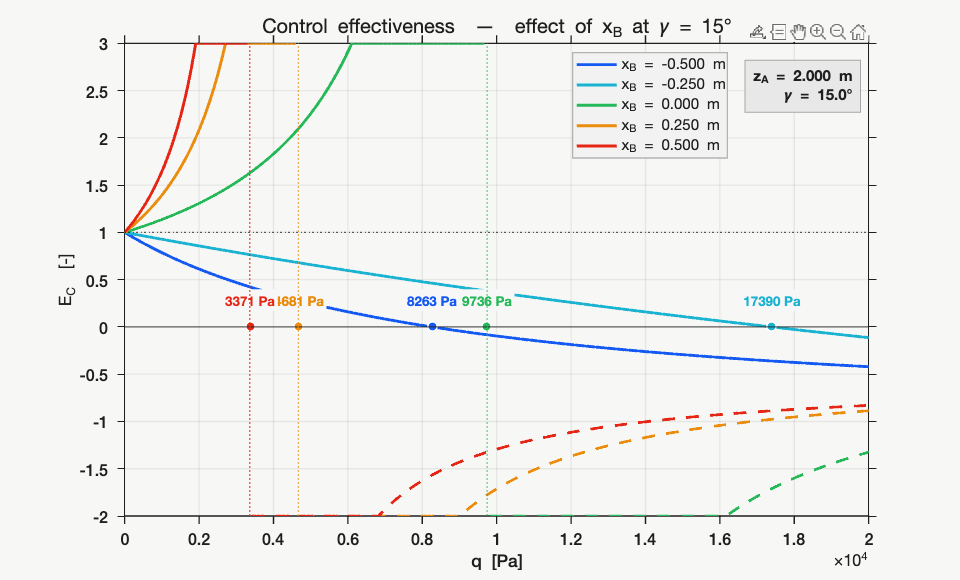

%% ── E_C(q) for several x_B at fixed gamma ──────────────────────────────

xB_list = [-c/2, -c/4, 0, c/4, c/2];

CMAP = [ ...
    0.08 0.35 0.95;
    0.10 0.70 0.82;
    0.15 0.72 0.35;
    0.92 0.55 0.05;
    0.90 0.15 0.08];

%% ── Manual plot limits (set [] for automatic) ─────────────────────────
X_LIM = [0, 2e4];
Y_LIM = [-2, 3];

fig = figure('Color', BG, 'Position', [100 80 960 580]);
ax  = axes('Parent', fig, ...
    'Color', BG, 'XColor', FG, 'YColor', FG, ...
    'GridColor', [0 0 0], 'GridAlpha', 0.07, ...
    'Box', 'on', 'LineWidth', 1.0, ...
    'FontName', FNT, 'FontSize', 12, 'TickDir', 'out');
hold(ax,'on'); grid(ax,'on');

yline(ax, 0, 'Color', [FG 0.4], 'LineWidth', 1.0, 'HandleVisibility', 'off');
yline(ax, 1, 'Color', [FG 0.25], 'LineStyle', ':', 'LineWidth', 1.0, 'HandleVisibility', 'off');

qR_vals = NaN(size(xB_list));

for i = 1:numel(xB_list)
    xB  = xB_list(i);
    col = CMAP(i,:);

    qD_i = q_D(gamma, xB);
    qR_i = find_qR(@(q) E_C(gamma, xB, q), qD_i);
    qR_vals(i) = qR_i;

    %% Raw evaluation
    EC_raw = arrayfun(@(q) E_C(gamma, xB, q), q_vec);

    %% Display version: keep divergence visible by clipping to Y_LIM
    EC_plot = EC_raw;

    if ~isempty(Y_LIM)
        EC_plot(EC_plot > Y_LIM(2)) = Y_LIM(2);
        EC_plot(EC_plot < Y_LIM(1)) = Y_LIM(1);
        EC_plot(isinf(EC_raw) & EC_raw > 0) = Y_LIM(2);
        EC_plot(isinf(EC_raw) & EC_raw < 0) = Y_LIM(1);
    end

    % Only suppress truly undefined values
    EC_plot(isnan(EC_raw)) = NaN;

    %% Plot left/right of divergence
    if isfinite(qD_i) && qD_i > 0
        eps_q = 1e-3 * q_max_plot;
        idxL = q_vec < qD_i - eps_q;
        idxR = q_vec > qD_i + eps_q;

        plot(ax, q_vec(idxL), EC_plot(idxL), ...
            'Color', col, 'LineWidth', 2.2, ...
            'DisplayName', sprintf('x_B = %.3f m', xB));

        plot(ax, q_vec(idxR), EC_plot(idxR), ...
            'Color', col, 'LineWidth', 2.2, 'LineStyle', '--', ...
            'HandleVisibility', 'off');

        xline(ax, qD_i, ...
            'Color', [col 0.30], ...
            'LineStyle', ':', ...
            'LineWidth', 1.0, ...
            'HandleVisibility', 'off');
    else
        plot(ax, q_vec, EC_plot, ...
            'Color', col, 'LineWidth', 2.2, ...
            'DisplayName', sprintf('x_B = %.3f m', xB));
    end

    %% ── Mark actual zero-crossings of E_C = 0 ─────────────────────────
    valid_pair = isfinite(EC_raw(1:end-1)) & isfinite(EC_raw(2:end));

    cross_pair = valid_pair & ( ...
        (EC_raw(1:end-1) == 0) | ...
        (EC_raw(2:end)   == 0) | ...
        (EC_raw(1:end-1) .* EC_raw(2:end) < 0) );

    idx_cross = find(cross_pair);
    q0_list = [];

    for k = idx_cross(:).'
        q1 = q_vec(k);
        q2 = q_vec(k+1);
        e1 = EC_raw(k);
        e2 = EC_raw(k+1);

        if e1 == 0
            q0 = q1;
        elseif e2 == 0
            q0 = q2;
        else
            % Linear interpolation of the zero crossing
            q0 = q1 - e1 * (q2 - q1) / (e2 - e1);
        end

        q0_list(end+1) = q0; %#ok<SAGROW>
    end

    % Remove possible duplicates
    if ~isempty(q0_list)
        q0_list = unique(round(q0_list, 10));

        % Plot zero-crossing markers
        plot(ax, q0_list, zeros(size(q0_list)), 'o', ...
            'MarkerSize', 7, ...
            'MarkerFaceColor', col, ...
            'MarkerEdgeColor', [1 1 1], ...
            'LineWidth', 1.2, ...
            'HandleVisibility', 'off');

        % Vertical offset for annotations
        if ~isempty(Y_LIM)
            dy = 0.04 * (Y_LIM(2) - Y_LIM(1));
        else
            dy = 0.15;
        end

        % Annotate q value at each zero-crossing
        for iq = 1:numel(q0_list)
            if mod(iq,2)==1
                y_txt  = 0 + dy;
                vAlign = 'bottom';
            else
                y_txt  = 0 - dy;
                vAlign = 'top';
            end

            text(ax, q0_list(iq), y_txt, ...
                sprintf('%.0f Pa', q0_list(iq)), ...
                'Color', col, ...
                'FontName', FNT, ...
                'FontSize', 10, ...
                'FontWeight', 'bold', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', vAlign, ...
                'BackgroundColor', [0.97 0.97 0.97], ...
                'Margin', 2, ...
                'Clipping', 'on');
        end
    end
end

%% Text box position
if ~isempty(X_LIM)
    x_text = X_LIM(2) - 0.02*(X_LIM(2)-X_LIM(1));
else
    x_text = 0.98*q_max_plot;
end

if ~isempty(Y_LIM)
    y_text = Y_LIM(2) - 0.05*(Y_LIM(2)-Y_LIM(1));
else
    y_text = 2.7;
end

text(ax, x_text, y_text, ...
    sprintf('z_A = %.3f m\n\\gamma = %.1f°', z_A, gamma_deg), ...
    'FontName', FNT, ...
    'FontSize', 11, ...
    'FontWeight', 'bold', ...
    'Color', FG, ...
    'HorizontalAlignment', 'right', ...
    'VerticalAlignment', 'top', ...
    'BackgroundColor', [0.91 0.91 0.91], ...
    'EdgeColor', [0.65 0.65 0.65], ...
    'Margin', 5);

xlabel('q  [Pa]', 'Color', FG, 'FontName', FNT, 'FontSize', 13);
ylabel('E_C  [-]', 'Color', FG, 'FontName', FNT, 'FontSize', 13);
title(sprintf('Control effectiveness  —  effect of x_B at \\gamma = %.0f°', gamma_deg), ...
    'Color', FG, 'FontName', FNT, 'FontSize', 15, 'FontWeight', 'normal');

lg = legend('Location', 'northeast', 'FontSize', 11, 'FontName', FNT);
lg.TextColor = FG;
lg.EdgeColor = [0.70 0.70 0.70];
lg.Color     = [0.95 0.95 0.95];

%% ── Manual axes limits ─────────────────────────────────────────────────
if ~isempty(X_LIM)
    xlim(ax, X_LIM);
end

if ~isempty(Y_LIM)
    ylim(ax, Y_LIM);
end

## Reversal pressure as a function of the strut chordwise position

The reversal pressure is now extracted for a continuous range of (x_B) values.

This plot is the most direct one for evaluating the influence of the strut position on control reversal. It also allows the elastic axis and the aerodynamic center to be identified on the same graph.

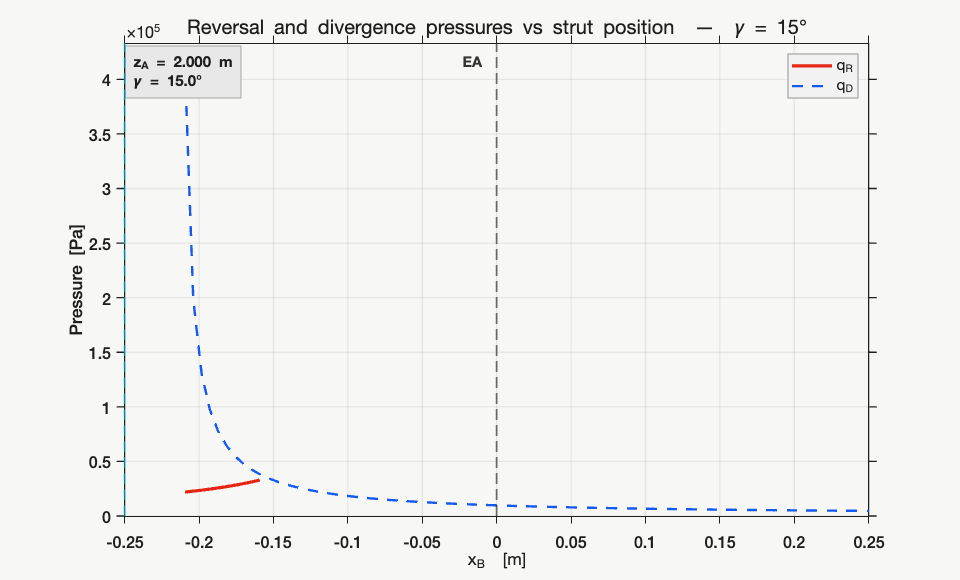

%% ── Reversal pressure q_R vs x_B at fixed gamma ────────────────────────

x_B_vec = linspace(-c/2, c/2, 180);
qR_xB   = NaN(size(x_B_vec));
qD_xB   = NaN(size(x_B_vec));

for i = 1:numel(x_B_vec)
    xB = x_B_vec(i);

    % Divergence pressure
    qD_i = q_D(gamma, xB);

    % Keep only positive q_D values for plotting
    if isfinite(qD_i) && qD_i > 0
        qD_xB(i) = qD_i;
    else
        qD_xB(i) = NaN;
    end

    % Reversal pressure:
    % compute it independently so that q_R can still be shown
    % even when it is above q_D
    qR_i = find_qR(@(q) E_C(gamma, xB, q), qD_i);

    if isfinite(qR_i) && qR_i > 0
        qR_xB(i) = qR_i;
    else
        qR_xB(i) = NaN;
    end
end

x_EA = 0;
x_AC = -c/4;

BG   = [0.97 0.97 0.96];
FG   = [0.12 0.12 0.12];
FNT  = 'Helvetica Neue';
C_QR = [0.90 0.15 0.08];
C_QD = [0.08 0.35 0.95];
C_EA = [0.20 0.20 0.20];
C_AC = [0.00 0.68 0.82];

fig = figure('Color', BG, 'Position', [100 80 960 580]);
ax  = axes('Parent', fig, ...
    'Color', BG, 'XColor', FG, 'YColor', FG, ...
    'GridColor', [0 0 0], 'GridAlpha', 0.07, ...
    'Box', 'on', 'LineWidth', 1.0, ...
    'FontName', FNT, 'FontSize', 12, 'TickDir', 'out');
hold(ax,'on'); grid(ax,'on');

plot(ax, x_B_vec, qR_xB, '-', ...
    'Color', C_QR, 'LineWidth', 2.4, ...
    'DisplayName', 'q_R');

plot(ax, x_B_vec, qD_xB, '--', ...
    'Color', C_QD, 'LineWidth', 1.8, ...
    'DisplayName', 'q_D');

xline(ax, x_EA, '--', 'Color', C_EA, 'LineWidth', 1.2, 'HandleVisibility', 'off');
xline(ax, x_AC, '--', 'Color', C_AC, 'LineWidth', 1.2, 'HandleVisibility', 'off');

% Zoom on x_B in [-c/4, 0]
xlim(ax, [-c/4, c/4]);

% Positive pressures only
q_all = [qR_xB(:); qD_xB(:)];
q_all = q_all(isfinite(q_all) & q_all > 0);

if ~isempty(q_all)
    ymin = 0;
    ymax = 1.05 * max(q_all);
    ylim(ax, [ymin, ymax]);
else
    ylim(ax, [0, 1]);
end

yl = ylim(ax);

text(x_EA - 0.01*c, yl(2)*0.98, 'EA', ...
    'Color', C_EA, 'FontName', FNT, 'FontSize', 11, 'FontWeight', 'bold', ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'top');

text(x_AC + 0.01*c, yl(2)*0.98, 'AC', ...
    'Color', C_AC, 'FontName', FNT, 'FontSize', 11, 'FontWeight', 'bold', ...
    'HorizontalAlignment', 'left', 'VerticalAlignment', 'top');

text(-c/4 + 0.02*(c/4), yl(2)*0.98, ...
    sprintf('z_A = %.3f m\n\\gamma = %.1f°', z_A, gamma_deg), ...
    'FontName', FNT, 'FontSize', 11, 'FontWeight', 'bold', ...
    'Color', FG, 'HorizontalAlignment', 'left', 'VerticalAlignment', 'top', ...
    'BackgroundColor', [0.91 0.91 0.91], ...
    'EdgeColor', [0.65 0.65 0.65], 'Margin', 5);

xlabel('x_B  [m]', 'Color', FG, 'FontName', FNT, 'FontSize', 13);
ylabel('Pressure  [Pa]', 'Color', FG, 'FontName', FNT, 'FontSize', 13);
title(sprintf('Reversal and divergence pressures vs strut position  —  \\gamma = %.0f°', gamma_deg), ...
    'Color', FG, 'FontName', FNT, 'FontSize', 15, 'FontWeight', 'normal');

lg = legend('Location', 'northeast', 'FontSize', 11, 'FontName', FNT);
lg.TextColor = FG;
lg.EdgeColor = [0.70 0.70 0.70];
lg.Color     = [0.95 0.95 0.95];

## **Combined influence of x_B and gamma**

In order to assess the combined effect of geometry and strut orientation, the reversal pressure is finally evaluated in the ((x_B,\gamma)) plane.

This representation highlights the regions where the strut is most effective in delaying reversal.

%% ── Map q_R(x_B, gamma) with physical filtering ───────────────────────

xB_grid       = linspace(-c/2, c/2, 100);
gamma_deg_vec = linspace(10, 20, 100);

[XB, GD] = meshgrid(xB_grid, gamma_deg_vec);
QR_map   = NaN(size(XB));

BG  = [0.97 0.97 0.96];
FG  = [0.12 0.12 0.12];
FNT = 'Helvetica Neue';

disp('Start map computation...')

Start map computation...


tic

for i = 1:size(XB,1)
    fprintf('Row %d / %d\n', i, size(XB,1));

    for j = 1:size(XB,2)
        g  = deg2rad(GD(i,j));
        xB = XB(i,j);

        % Divergence pressure at current point
        qD_ij = q_D(g, xB);

        % --- Physical / numerical filtering before calling find_qR ------
        if ~isfinite(qD_ij) || qD_ij <= 0
            QR_map(i,j) = NaN;
            continue;
        end

        % Optional: skip points too close to singular behavior if needed
        % if abs(qD_ij) < 1e-12
        %     QR_map(i,j) = NaN;
        %     continue;
        % end

        try
            qR_ij = find_qR(@(q) E_C(g, xB, q), qD_ij);

            % Keep only physical positive finite reversal pressures
            if isfinite(qR_ij) && qR_ij > 0
                QR_map(i,j) = qR_ij;
            else
                QR_map(i,j) = NaN;
            end

        catch ME
            QR_map(i,j) = NaN;
            fprintf(['Failed at i=%d, j=%d, gamma=%.3f deg, x_B=%.5f m : %s\n'], ...
                    i, j, GD(i,j), xB, ME.message);
        end
    end
end

Row 1 / 100
Row 2 / 100
Row 3 / 100
Row 4 / 100
Row 5 / 100
Row 6 / 100
Row 7 / 100
Row 8 / 100
Row 9 / 100
Row 10 / 100
Row 11 / 100
Row 12 / 100
Row 13 / 100
Row 14 / 100
Row 15 / 100
Row 16 / 100
Row 17 / 100
Row 18 / 100
Row 19 / 100
Row 20 / 100
Row 21 / 100
Row 22 / 100
Row 23 / 100
Row 24 / 100
Row 25 / 100
Row 26 / 100
Row 27 / 100
Row 28 / 100
Row 29 / 100
Row 30 / 100
Row 31 / 100
Row 32 / 100
Row 33 / 100
Row 34 / 100
Row 35 / 100
Row 36 / 100
Row 37 / 100
Row 38 / 100
Row 39 / 100
Row 40 / 100
Row 41 / 100
Row 42 / 100
Row 43 / 100
Row 44 / 100
Row 45 / 100
Row 46 / 100
Row 47 / 100
Row 48 / 100
Row 49 / 100
Row 50 / 100
Row 51 / 100
Row 52 / 100
Row 53 / 100
Row 54 / 100
Row 55 / 100
Row 56 / 100
Row 57 / 100
Row 58 / 100
Row 59 / 100
Row 60 / 100
Row 61 / 100
Row 62 / 100
Row 63 / 100
Row 64 / 100
Row 65 / 100
Row 66 / 100
Row 67 / 100
Row 68 / 100
Row 69 / 100
Row 70 / 100
Row 71 / 100
Row 72 / 100
Row 73 / 100
Row 74 / 100
Row 75 / 100
Row 76 / 100
Row 77 / 100
Row 78 /


toc

Elapsed time is 14.504085 seconds.


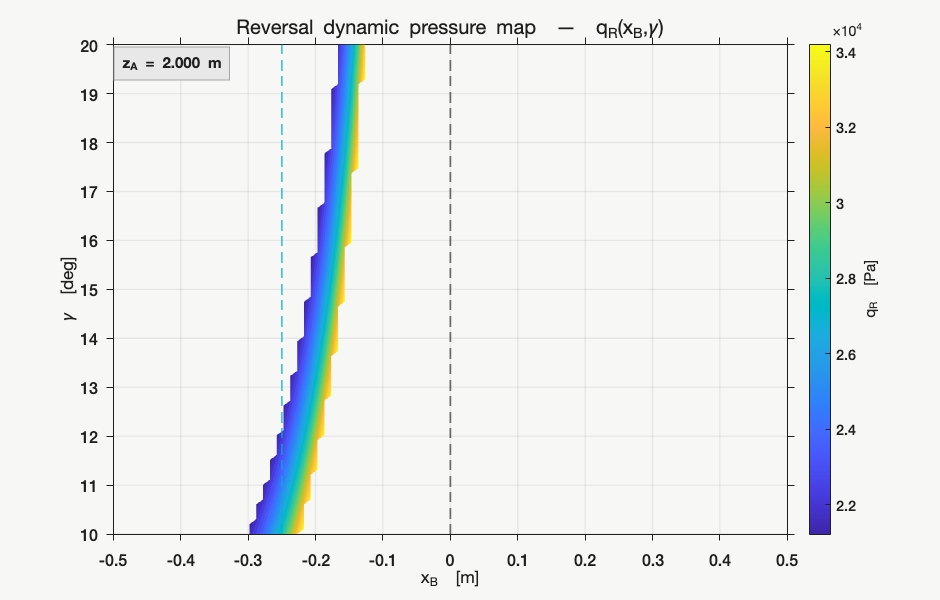


%% ── Plot ───────────────────────────────────────────────────────────────

fig = figure('Color', BG, 'Position', [100 80 940 600]);
ax  = axes('Parent', fig, ...
    'Color', BG, 'XColor', FG, 'YColor', FG, ...
    'FontName', FNT, 'FontSize', 12, ...
    'GridColor', [0 0 0], 'GridAlpha', 0.07, ...
    'Box', 'on', 'LineWidth', 1.0, 'TickDir', 'out');
hold(ax,'on'); grid(ax,'on');

contourf(ax, XB, GD, QR_map, 24, 'LineColor', 'none');
colormap(ax, parula);

cb = colorbar(ax);
cb.Label.String   = 'q_R  [Pa]';
cb.Label.FontName = FNT;
cb.Label.FontSize = 11;
cb.Color          = FG;

xline(ax, 0, '--', ...
    'Color', [0.2 0.2 0.2], ...
    'LineWidth', 1.2, ...
    'HandleVisibility', 'off');

xline(ax, -c/4, '--', ...
    'Color', [0.0 0.68 0.82], ...
    'LineWidth', 1.2, ...
    'HandleVisibility', 'off');

text(0.01, 0.98, sprintf('z_A = %.3f m', z_A), ...
    'Units', 'normalized', ...
    'FontName', FNT, 'FontSize', 11, 'FontWeight', 'bold', ...
    'Color', FG, ...
    'HorizontalAlignment', 'left', ...
    'VerticalAlignment', 'top', ...
    'BackgroundColor', [0.91 0.91 0.91], ...
    'EdgeColor', [0.65 0.65 0.65], ...
    'Margin', 5);

xlabel('x_B  [m]', ...
    'Color', FG, 'FontName', FNT, 'FontSize', 13);

ylabel('\gamma  [deg]', ...
    'Color', FG, 'FontName', FNT, 'FontSize', 13);

title('Reversal dynamic pressure map  —  q_R(x_B,\gamma)', ...
    'Color', FG, 'FontName', FNT, 'FontSize', 15, 'FontWeight', 'normal');

**Minimal interpretation text to add after the plots****Discussion**

The results show that the strut does not only affect divergence, but also modifies the reversal dynamic pressure through the additional bending–torsion coupling it introduces. The parameter (x_B) has a direct influence on this coupling because it appears in the attachment displacement (h_B = w(y_B) - x_B \theta(y_B)). As a consequence, the strut position may significantly delay or anticipate the onset of control reversal.

The map (q_R(x_B,\gamma)) is particularly useful because it makes it possible to identify the combinations of strut position and inclination that are the most favorable from a control point of view. In practice, the most efficient configurations are those for which the strut increases the effective structural stiffness while limiting the torsional deformation responsible for reversal.